clear

vn100_log = fileread("vn100_datalog.txt");
entries = char(splitlines(vn100_log));

N = size(entries,1);
% create one example output then preallocate by replicating it
example = parse_vnqmr(entries(1,:));   % use safe parser
result = repmat(example, N, 1);

for k = 1:size(entries,1)
    result(k) = parse_vnqmr(entries(k,:));
    if result(k).Valid == true
        q = [result(k).q(4),result(k).q(1:3)];
        att(k,:) = quat2eul(q);
        mag(k,:) = result(k).mag;
        accel(k,:) = result(k).accel;
        gyro(k,:) = result(k).gyro;
    end

    if result(k).Type ~= 'VNQMR' && result(k).Type ~= ""
        result(k).Type
    end
end

function out = parse_vnqmr(s)
% parse_vnqmr_safe Parse VNQMR-like sentence without throwing errors.
%   out = parse_vnqmr_safe(s)
%   If input is malformed, out.Valid is false and other fields are empty.
%
% Example:
%   s = "$VNQMR,+0.050172,...*42";
%   out = parse_vnqmr_safe(s);

% Initialize output defaults
out = struct(...
    'Valid', false, ...
    'Type', string(""), ...
    'q', [], ...
    'mag', [], ...
    'accel', [], ...
    'gyro', [], ...
    'ChecksumOK', false);

if isempty(s)
    return
end

s = char(s(:).');            % ensure row char
s = strtrim(s);

% must start with $
if isempty(s) || s(1) ~= '$'
    return
end

% find '*' delimiter; if missing, consider invalid but continue parsing body
starIdx = find(s == '*', 1, 'first');
if isempty(starIdx)
    body = s(2:end);
    givenChk = "";
else
    body = s(2:starIdx-1);
    givenChk = upper(strtrim(s(starIdx+1:end)));
    if isempty(givenChk)
        givenChk = "";
    end
end

% compute XOR checksum of body bytes (if body non-empty)
if ~isempty(body)
    chk = uint8(0);
    for k = 1:numel(body)
        chk = bitxor(chk, uint8(body(k)));
    end
    calcChk = upper(string(dec2hex(double(chk),2)));
else
    calcChk = "";
end

% split body by commas and require at least a type token
parts = split(body, ',');
if isempty(parts)
    return
end

typ = strtrim(parts{1});
if isempty(typ)
    return
end

% convert numeric fields; ignore conversion errors (yield NaN)
numParts = parts(2:end);
numParts(cellfun(@(x) isempty(strtrim(x)), numParts)) = []; % drop empty tokens
numVals = nan(1,numel(numParts));
for k = 1:numel(numParts)
    % str2double returns NaN for non-numeric strings
    numVals(k) = str2double(strtrim(numParts{k}));
end

if length(numVals) ~= 13
    return
end



% fill output
out.Valid = true;
out.Type = string(typ);
out.q = numVals(1:4);
out.mag = numVals(5:7);
out.accel = numVals(8:10);
out.gyro = numVals(11:13);
out.ChecksumOK = ~isempty(calcChk) && ~isempty(givenChk) && strcmpi(char(calcChk), char(givenChk));

end



t = linspace(0,size(entries,1)/40,size(entries,1)-1)

t =          0    0.0250    0.0500    0.0751    0.1001    0.1251    0.1501    0.1752    0.2002    0.2252    0.2502    0.2752    0.3003    0.3253    0.3503    0.3753    0.4003    0.4254    0.4504    0.4754    0.5004    0.5255    0.5505    0.5755    0.6005    0.6255    0.6506    0.6756    0.7006    0.7256    0.7506    0.7757    0.8007    0.8257    0.8507    0.8758    0.9008    0.9258    0.9508    0.9758    1.0009    1.0259    1.0509    1.0759    1.1009    1.1260    1.1510    1.1760    1.2010    1.2261


tidx = find(t>=4,1,'first');
t = t(tidx:end);
att = att(tidx:end,:);
mag = mag(tidx:end,:);
accel = accel(tidx:end,:);
gyro = gyro(tidx:end,:);


std(att)

ans =     1.5556    0.2686    0.5853



std(mag)

ans =     0.1434    0.1547    0.2058



std(accel)

ans =     2.1600    2.2826    3.4012



std(gyro)

ans =     1.2593    0.9873    1.0396


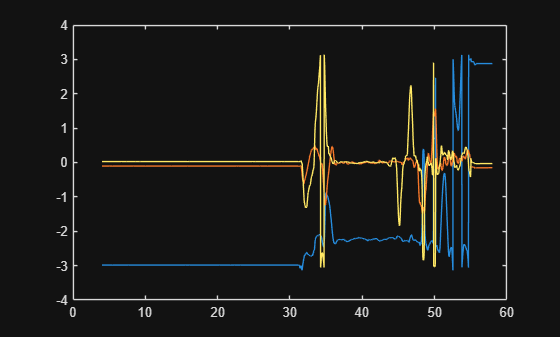



figure
plot(t,att)

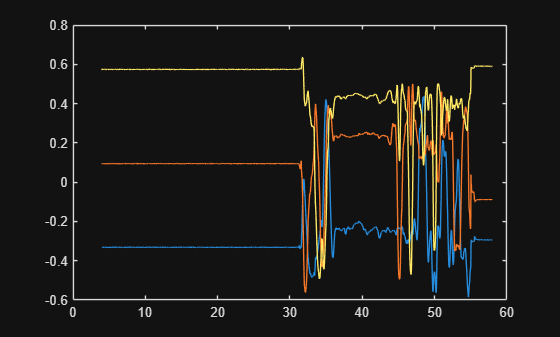


figure
plot(t,mag)

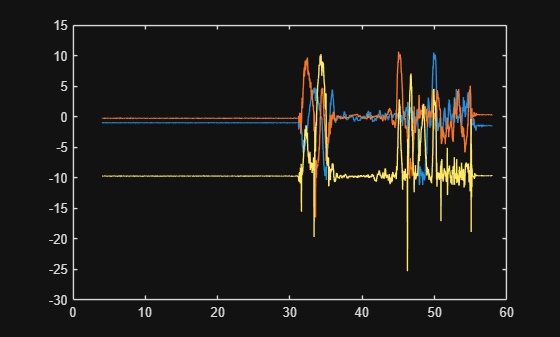


figure
plot(t,accel)

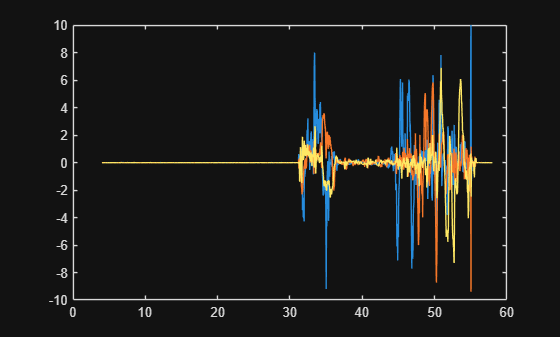


figure
plot(t,gyro)